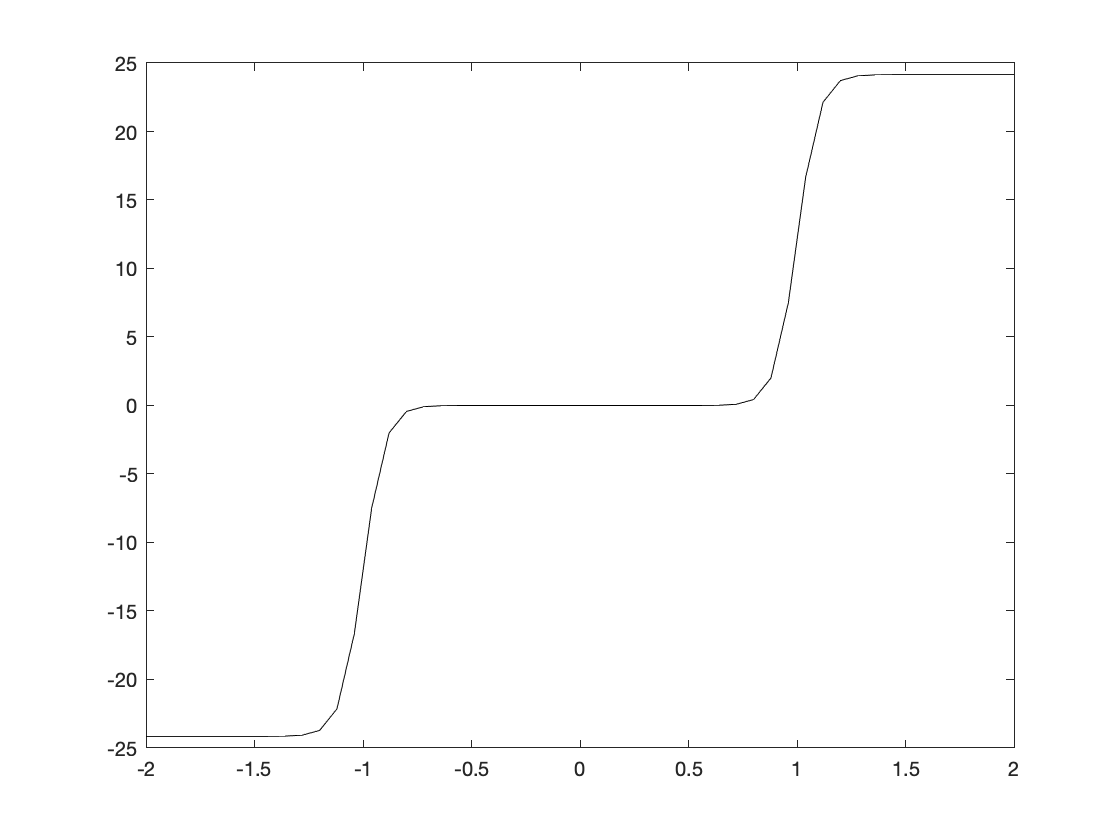

E0 = -5.5; 
Ef = -5;
gam1 = 0.1 ; 
gam2 = 0.1;
U = 0 ; %Constants (all MKS, except energy which is in eV) 
hbar = 1.06e-34;q = 1.6e-19;IE = (2*q*q)/hbar;
kT = .025; % Bias (calculate 101 voltage points in [-4 4] range) 
nV = 101;VV = linspace(-4,4,nV);dV = VV(2)-VV(1); N0 = 2/ (1 + exp((E0-Ef)/kT) ) ; 
for iV = 1:nV% Voltage loop 
    UU = 0;dU = 1;

    V = VV(iV);mu1 = Ef-(V/2);mu2 = Ef+(V/2); 

    while dU>1e-6%SCF 
        E = E0+UU;

        f1 = 1/(1+exp((E-mu1)/kT));f2 = 1/(1+exp((E-mu2)/kT)); NN = 2* ( (gam1*f1) + (gam2*f2))/(gam1 + gam2) ; % Charge 
        Uold = UU;UU = Uold+(.05*((U*(NN-N0))-Uold)); dU = abs (UU-Uold) ; [V UU dU] ;

    end

    curr = IE*gam1*gam2 *(f2-f1)/(gam1+gam2) ; 
    II(iV) = curr ;
    N(iV) = NN; 
end

[V NN] ;
voltU0 = figure;
G = diff(II)/dV;GG = [G(1) G] ; % Conductance 
voltU0plot = plot(VV,II*10^6,'k');% Plot I-V
xlim([-2 2])

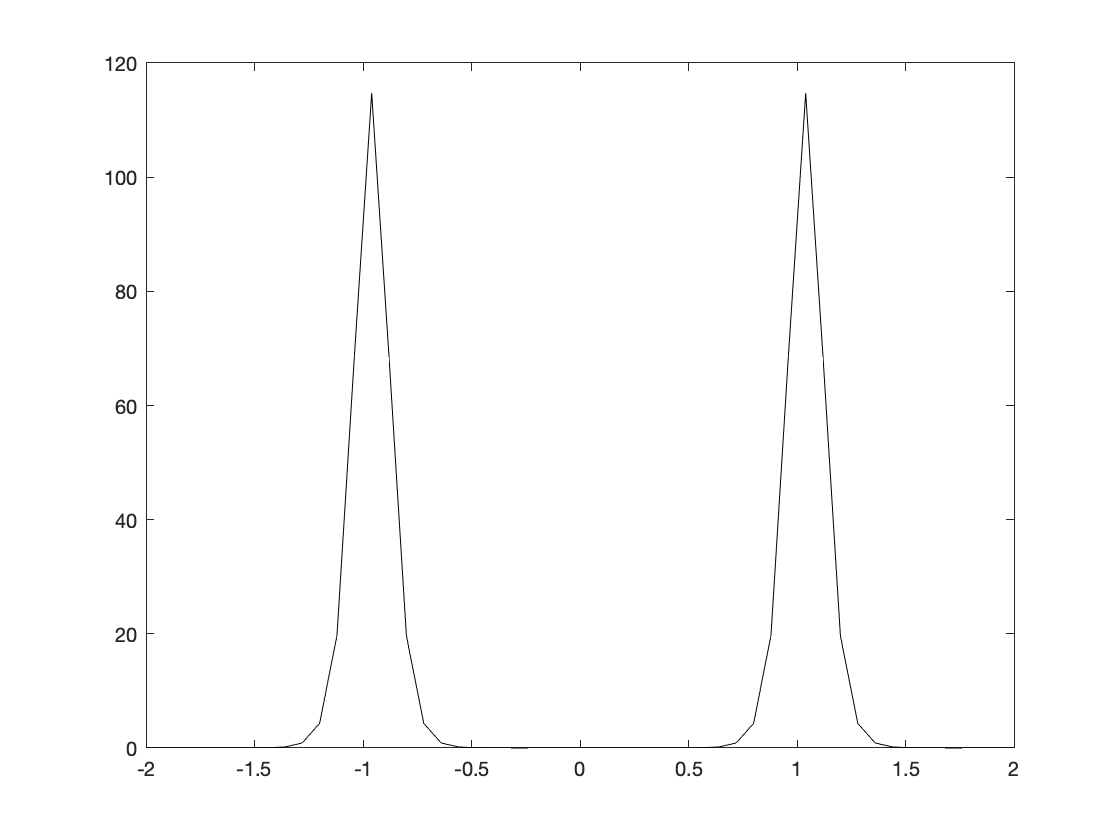

condU0 = figure;
condU0plot = plot(VV,GG*10^6, 'k');
xlim([-2 2])

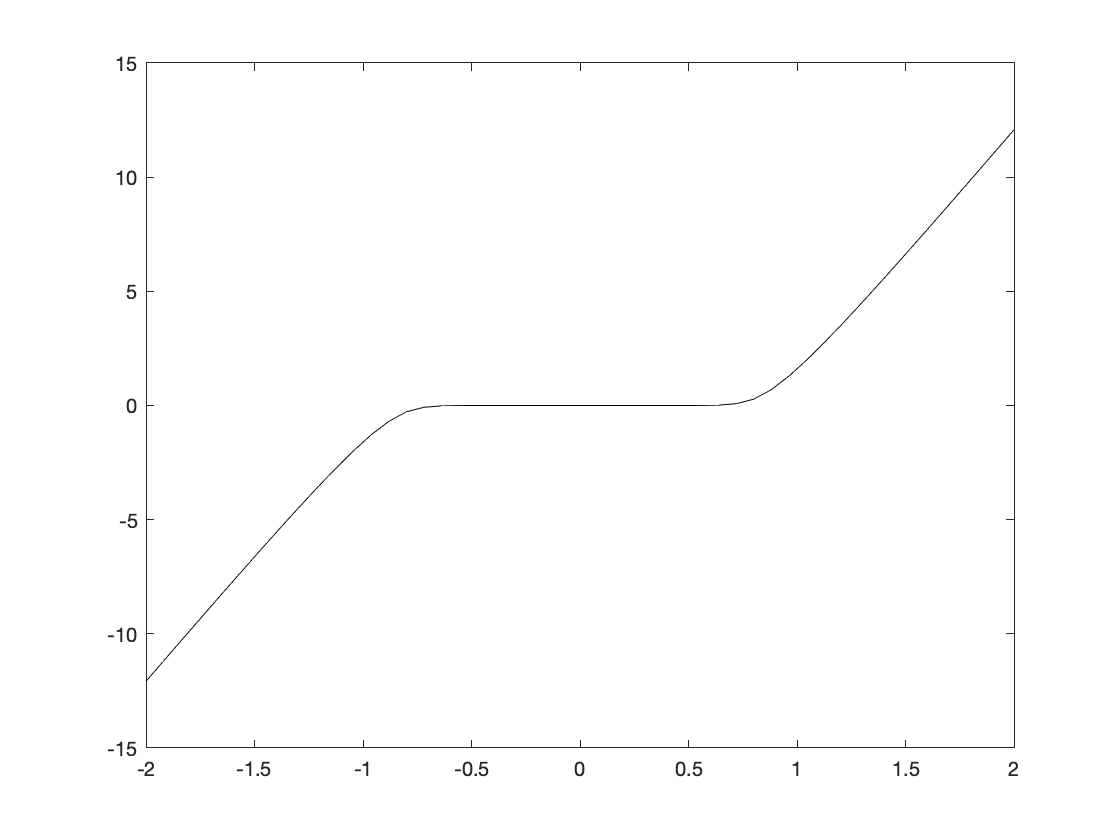



U = 1 ; %Constants (all MKS, except energy which is in eV) 
hbar = 1.06e-34;q = 1.6e-19;IE = (2*q*q)/hbar;
kT = .025; % Bias (calculate 101 voltage points in [-4 4] range) 
nV = 101;VV = linspace(-4,4,nV);dV = VV(2)-VV(1); N0 = 2/ (1 + exp((E0-Ef)/kT) ) ; 
for iV = 1:nV% Voltage loop 
    UU = 0;dU = 1;

    V = VV(iV);mu1 = Ef-(V/2);mu2 = Ef+(V/2); 

    while dU>1e-6%SCF 
        E = E0+UU;

        f1 = 1/(1+exp((E-mu1)/kT));f2 = 1/(1+exp((E-mu2)/kT)); NN = 2* ( (gam1*f1) + (gam2*f2))/(gam1 + gam2) ; % Charge 
        Uold = UU;UU = Uold+(.05*((U*(NN-N0))-Uold)); dU = abs (UU-Uold) ; [V UU dU] ;

    end

    curr = IE*gam1*gam2 *(f2-f1)/(gam1+gam2) ; 
    II(iV) = curr ;
    N(iV) = NN; 
end

[V NN] ;
voltU1 = figure;
G = diff(II)/dV;GG = [G(1) G] ; % Conductance 
voltU1plot = plot(VV,II*10^6,'k');% Plot I-V
xlim([-2 2])

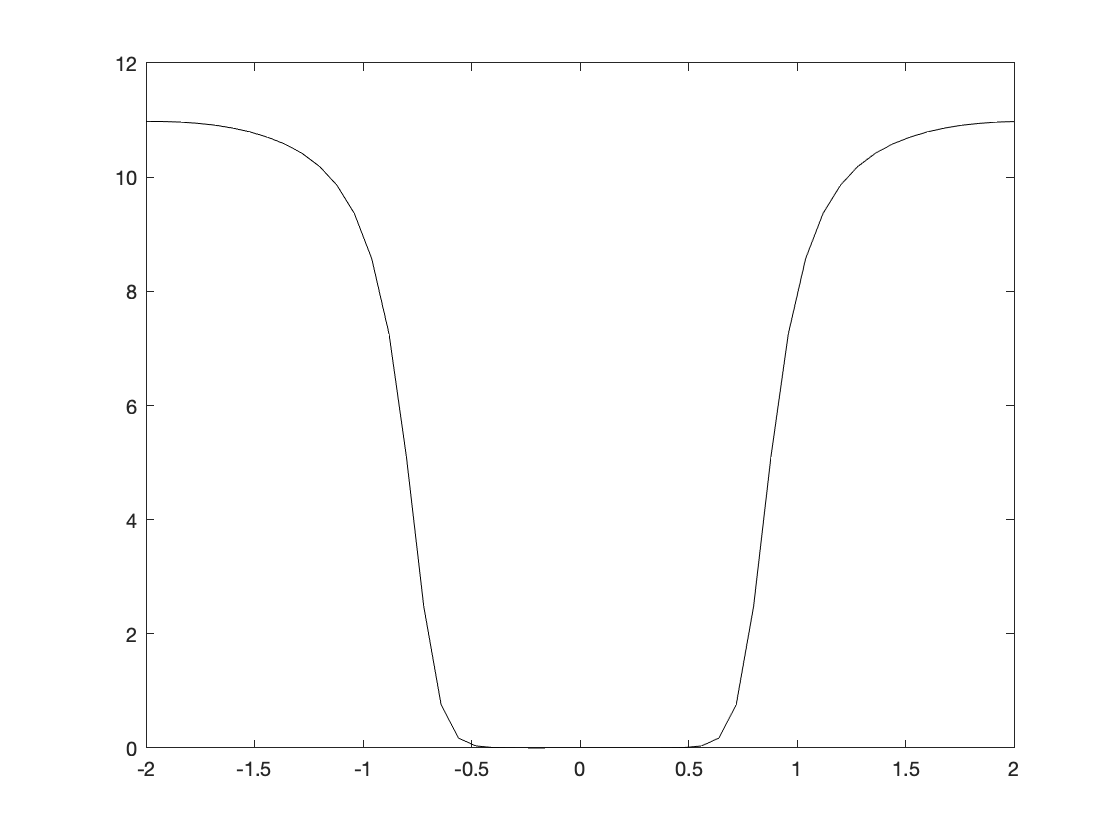


condU1 = figure;
condU1plot = plot(VV,GG*10^6, 'k');
xlim([-2 2])

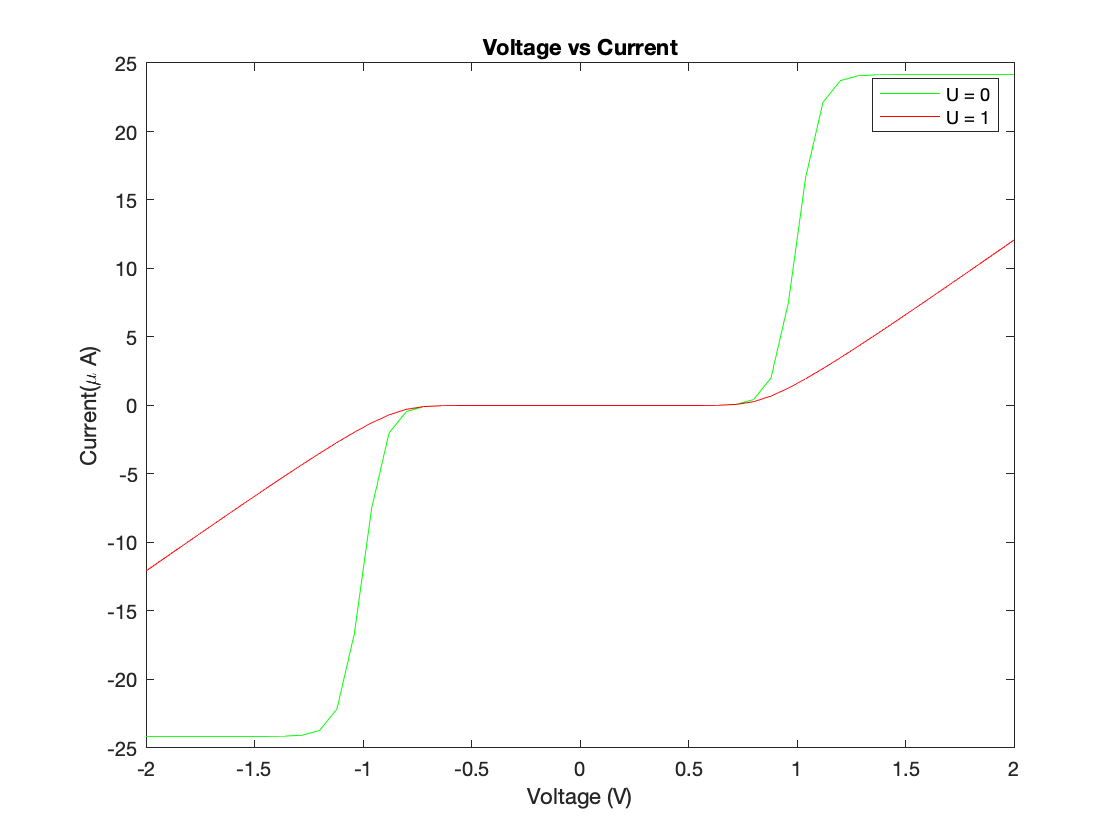

[VV, II, GG] = q9plzwork(0);

[VV2, II2, GG2] = q9plzwork(1);

voltVScurrent = figure;
plot(VV,II*10^6,'G', VV2,II2*10^6,'r')
ylabel('Current(\mu A)')
xlabel('Voltage (V)')
title('Voltage vs Current')
legend('U = 0', 'U = 1')
xlim([-2 2])

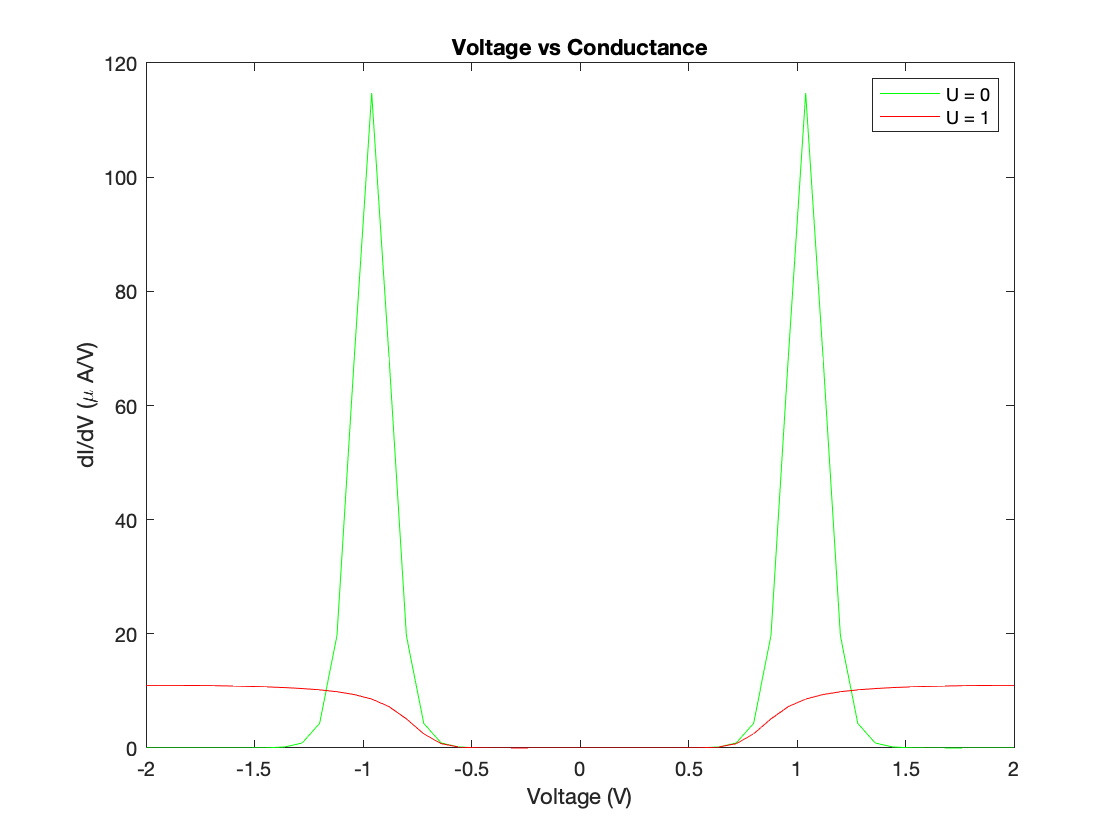

voltVSconductance = figure;
voltPlot = plot(VV,GG*10^6,'G',VV2,GG2*10^6, 'r');
ylabel('dI/dV (\mu A/V)')
xlabel('Voltage (V)')
title('Voltage vs Conductance')
legend('U = 0', 'U = 1')
xlim([-2 2])


import mlreportgen.report.*                                                 %Import Report API and DOM API packages
import mlreportgen.dom.*

disp("Generating Project 3 Report...")

Generating Project 3 Report...



doctype = "docx";                                                           %Specify document type for report
rpt = Report("HW3 Report",doctype);                                %Create Report container
rpt.Layout.PageNumberFormat = "i";

tp = TitlePage;                                                             %Create title page reporter
tp.Title = "HW3 Report";                             %Specify title
tp.Author= "Eddie, Summer, Ani";

add(rpt,tp)                                                                 %Add title page to the report    


p = Paragraph("hellow world");
append(rpt,p);
    
fig1 = Figure(voltVScurrent);                                %Formating image for report
fig1.Scaling = 'custom';
fig1.SnapshotFormat = 'svg';
img = Image(getSnapshotImage(fig1, rpt));

img.Height = "4in";
img.Width = "4.5in";
append(rpt,img);

fig1 = Figure(voltVSconductance);                                %Formating image for report
fig1.Scaling = 'custom';
fig1.SnapshotFormat = 'svg';
img = Image(getSnapshotImage(fig1, rpt));
img.Height = "4in";
img.Width = "4.5in";
append(rpt,img);


close(rpt)                                                          %Close the report
% docview("Project3_Hackett_Report.docx",...
%     "updatefields","showdocxaspdf","closeapp")                      % View the report and convert to PDF
% rptview(rpt)                                                      % Another way to view the report
disp("DONE.")

DONE.


function [VV, II, GG] = q9plzwork(U)
    E0 = -5.5; 
    Ef = -5;
    gam1 = 0.1 ; 
    gam2 = 0.1;
%     U = 0 ; %Constants (all MKS, except energy which is in eV) 
    hbar = 1.06e-34;q = 1.6e-19;IE = (2*q*q)/hbar;
    kT = .025; % Bias (calculate 101 voltage points in [-4 4] range) 
    nV = 101;VV = linspace(-4,4,nV);dV = VV(2)-VV(1); N0 = 2/ (1 + exp((E0-Ef)/kT) ) ; 
    for iV = 1:nV% Voltage loop 
        UU = 0;dU = 1;
    
        V = VV(iV);mu1 = Ef-(V/2);mu2 = Ef+(V/2); 
    
        while dU>1e-6%SCF 
            E = E0+UU;
    
            f1 = 1/(1+exp((E-mu1)/kT));f2 = 1/(1+exp((E-mu2)/kT)); NN = 2* ( (gam1*f1) + (gam2*f2))/(gam1 + gam2) ; % Charge 
            Uold = UU;UU = Uold+(.05*((U*(NN-N0))-Uold)); dU = abs (UU-Uold) ; [V UU dU] ;
    
        end
    
        curr = IE*gam1*gam2 *(f2-f1)/(gam1+gam2) ; 
        II(iV) = curr ;
        N(iV) = NN; 
    end
    
    [V NN] ;
%     voltU0 = figure;
    G = diff(II)/dV;GG = [G(1) G] ; % Conductance 
%     voltU0plot = plot(VV,II*10^6,'k');% Plot I-V
end

